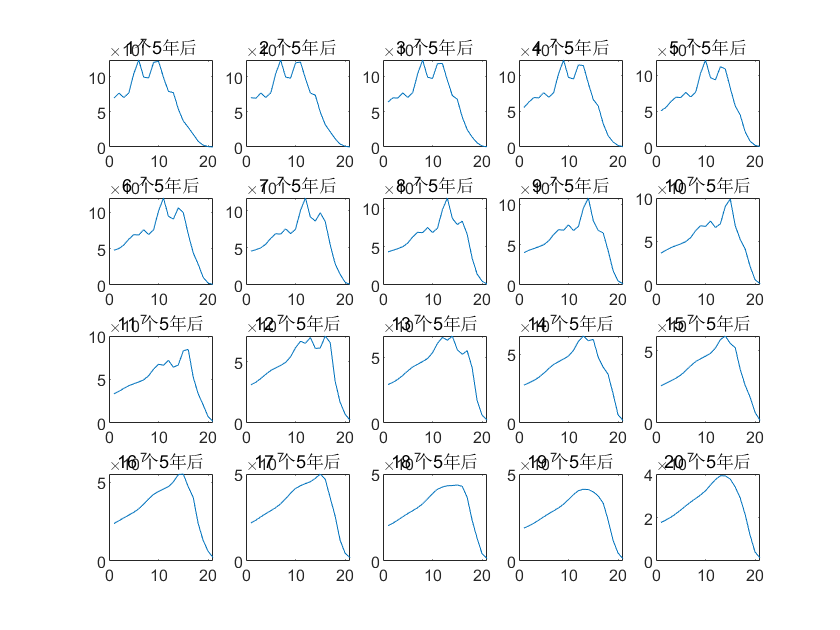

clear;
D=load('./dataforpeoplenumber.txt');
DR=(D(:,2));
BR=(D(:,3));
%各个年龄段人口数量，20*5，100年数据
N=zeros(21,5);
N(:,1)=specific_people(D(:,1),DR,BR);
subplot(4,5,1);
plot(N(:,1));
title('1个5年后');
for i=2:1:20
    N(:,i)=specific_people(N(:,i-1),DR,BR);
    subplot(4,5,i);
    plot(N(:,i));
    title([num2str(i),' 个5年后']);
end

%%总人口变化
figure;
M=sum(N)

M = 	1.0e+09 *

    1.3666    1.3942    1.4063    1.4005    1.3794    1.3448    1.2981    1.2412    1.1758    1.1047    1.0322    0.9612    0.8928    0.8283    0.7695    0.7165    0.6673    0.6208    0.5769    0.5358


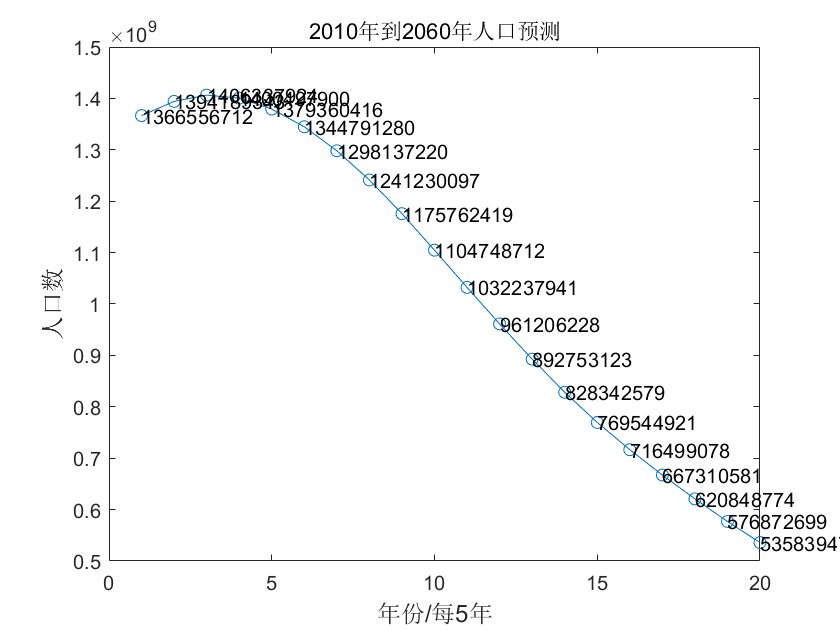

plot(M,'-o');
%set(gca,'XTick',2010:5:2060);
t=size(M,2);
for i=1:1:t
    text(i,M(1,i),num2str(M(1,i)));
end
%D各年龄段人口DR各年龄段死亡率BR各年龄段出生率
title('2010年到2060年人口预测')
xlabel('年份/每5年', 'fontsize',12)
ylabel('人口数','fontsize',12)

function [N]=specific_people(D,DR,BR)
N=zeros(21,1);
for i=21:(-1):1
    if i==1
        b=0;
        for j=1:1:21
            b=b+round(D(j,1)*BR(j,1)/1000);
        end
        
        N(i,1)=round(b*(1-DR(1,1)/1000)^4+b*(1-DR(1,1)/1000)^3+b*(1-DR(1,1)/1000)^2+b*(1-DR(1,1)/1000)+b);
    else if i==21
            N(i,1)=round(D(i,1)*(1-DR(i,1)/1000)^5+D(i-1,1)*(1-DR(i-1,1)/1000)^5);
    else
        N(i,1)=round(D(i-1,1)*(1-DR(i-1,1)/1000)^5);
    end
    end
end
end